# CameraSimulation

Simulates camera operation by transforming points known in world coordinates to camera snsor image coordinates using pinhole camera model. The mathematics of image formation with a pinhole camera is introduced. The camera parameters are chosen to simulate an iPhone 7 back camera as characterized by a 3dRuler lab camera calibration procedure. This virtual camera is then used to view a ballistic trajectory and a simulated checkerboard.

Author: D. Carlsmith

## Mathematics of pinhole camera imaging

Let's take a coordinate origin within the plane of an image sensor with unit normal $n$. Let  $x$ denote the coordinate vector of a point-like object and let $y$ denote the coordinate vector of its image through a pinhole located at a vector$f$. We have by vector addition (draw it out!)

 
$$y = f+\lambda (f-x)$$


where the scalar  $\lambda$ may be determined by the constraint that $y$ and $n$ are orthogonal,i.e. $y\cdot n=0$. We have

$n\cdot y = n\cdot f +\lambda n\cdot(f-x)=0\rightarrow\lambda=-n\cdot f/n\cdot (f-x)$.

We deduce the relationship between object and image coordinates:

 $y = (1+\lambda) f -\lambda x  = -{n\cdot x\over n\cdot(f-x)}f+{n\cdot f\over n\cdot(f-x)} x$.

If we shift the origin of coordinates within the sense plane to the optical center point where $f$ projects to along $n$, and suppose the sensor is oriented with the 3-axis along $n$, then we have the simpler component value relationships

$y_1={f\over{f-x_3}}x_1$, $y_2={f\over{f-x_3}}x_2$  and $y_3 = 0$ 

with $f=|f|$. The image transverse coordinates $y_1$ and $y_2$ are the object transverse coordinates $x_1$ and $x_2$ scaled by a magnification factor M=$-f/d$ with $d=x_3-f >0$, a result which follows from similar triangles. In comparison, a single thin refractive lens of focal length $f$ focuses light from a distance $s_o>f$ from the lens to a point at a distance $s_i$ on the other side of the lens with


$$1/s_i+1/s_0=1/f$$


and linear magnification $M=-f/(s_0-f)$where $s_0$ is the distance from the lens rather than from the image plane. 

## iPhone parameters in pinhole camera model

The effective focal length of an iPhone 7 back camera is $f=3.99$ mm according to EXIF data recorded with images, and the near point about 100 mm so $s_o-f\simeq s_o\simeq x_3$ and the pinhole model focal length $f$ is approximately equal to the effective focal length of the camera lens system. If the sensor is 4.80 mm x 3.60 mm and contains 4032 pixels x 3024 pixels, the pixels are p=1.19 micron on a side, and f/ p=3352. In landscape mode, the angular dimension of the horizontal field of view would be $\pm \tan^{-1}(2.4 ~{\rm mm}/4~{\rm mm} ) = \pm 30~{\rm deg}$ and the vertical dimension of the field of view would be $\pm 24$ deg.  See [http://exif.regex.info/exif.cgi](http://exif.regex.info/exif.cgi) to obtain EXIF information about your photos. 

My camera calibration process with a printed checkerboard in portrait mode yields  f/p=[3419,3414] close to these expectations. It also gives the position of the optical axis as o=[1562,2003] pixels to be compared to the central pix location of [1512,2016]. The two radial distortion parameters are k=[0.0443,-0.0418]. For larger images occupying about 1/4 of the frame, f/p=[3368,3354] (about 1.5% lower),o=[1556,2075] (the long component is shifted by 72 pixels or 3%. The radial distortion parameters are k=[0.0110,-.0300]. There are about 40 images in each set. Autofocusing was on and could have had an impact. The small picture set was taken to better approximate focus at infinity.

uiscopes.close('All'); % close videoplayers
clearvars;% clear variables in workspace
delete(findall(0,'Type','figure'));% clear figures

## Simulation of iPhone camera view of a ballistic trajectory

Generate a ballistic trajectory, plot it, then superpose a pinhole image for various parameter values. Use a right handed coordinate system with unit vectors $n_1$ horizontal (right), $n_2$ vertical (up), and $n_3$(backward) horizontal. Choose a trajectory in a 1-2 plane at a z distance in the negative z (forward) direction so its trajectory as normally plotted will move from right to left while accelerating downwards. That plane is at z=-3 m from the camera.

Initialize parameter values and compute dimensions of view provided by a camera with the parameter values above.

fmag0= .00399;% focal length
pixel= 1.9*10^(-6);% size of side of a square pixel (m)
pixel=pixel/2; % better fit to phone
nx=4032;ny=3024;% number of pixels in each frame dimension (landscape mode)
pxmax=nx*pixel/2;pymax=ny*pixel/2;% max values within sensor if origin at center.
z0 = -3;% location of object plane (m) relative to the sensor plane
M = abs(z0/fmag0);% linear magnification
xm= pxmax*M; ym = pymax*M;% view frame limits in plane of trajectory
x0=[-xm;ym;z0];% trajectory starts upper left corner (3x1)
g= [0;-9.8;0];% acceleration of gravity 

Compute a trajectory that will just fit in the camera frame. We fix the trajectory to start horizontally at the top left leaving initial horizontal velocity to be  determined so the trajectory passes through the lower right corner at some time. We have 2 equations to determine the hoizontal velocity and the time values:


$$ym+(g_y/2)t^2 = -ym\rightarrow t=\sqrt{-4ym/g_y}$$


 
$$-xm+v_{0x}t = xm\rightarrow v_{0x}=2 xm/t=2xm\sqrt{-g_y/4ym}$$
 

tmax=sqrt(-4*ym/g(2));v0x=2*xm/tmax;
v0=[v0x;0;0];% initial velocity (3x1)

Now pick  equally spaced times along the trajectory and get coordinates of the particle at those times.

Npoint=1000;
t=[0:tmax/Npoint:tmax];% row vector of times (1xN)
x = x0+v0*t +(1/2)*g.*t.^2;% position vector at all the times (3xN)
x1= x(1,:);x2=x(2,:);x3=x(3,:);% individual coordinates v time (1xN)

Plot the trajectory.

figure
plot(x1,x2);hold on;axis image
title('Ballistic trajectory projected on sensor (various magnifications)')
xlabel('x (m)');ylabel('y (m)')

Compute the image coordinates corresponding to all of the trajectory points for various camera magnifications for the sensor centered on the origin and in the 1-2 plane. The pinhole is at negative z (forward into the page). The camera is "looking" away from the origin of the plot at (0,0,0).

leg=string('trajectory');% set first entry for plot legend
for fmag = fmag0./[1:3]% magnitude of pinhole distance (m)
    n1=[1;0;0];% sensor 1-direction (3x1)
    n2=[0;1;0];% sensor 2-direction
    n3=[0;0;1];% sensor 3-direction
    n=-n3; % direction of sensor towards pinhole
    f=fmag*n;% initial pinhole location
    lambda = -(n'*f)./(n'*(f-x));% n' = $n^T$= (3x1)
    y=(1+lambda).*f -lambda.*x;% image points on sensor(3xN) (m)

Project sensor points onto sensor directions and scale so actual magnification fits frame.

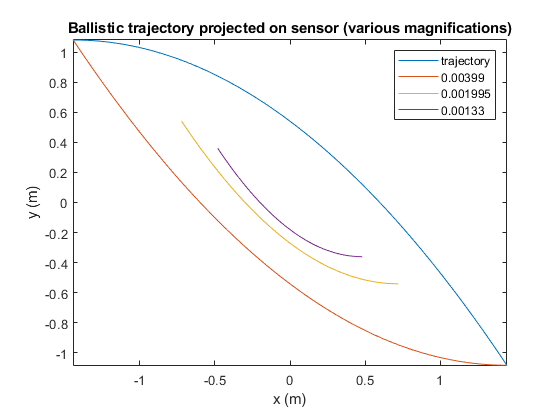

    plot(M*n1'*y,M*n2'*y,'-');hold on; axis image
    leg=[leg,string(fmag)];% build legend
end
legend('Trajectory',leg)% Add accumulated legend to plot
hold off

We see the image trajectory  is inverted, and compressed by the ratio of pinhole distance to object distance.

Look at the effect of rotation of the image plane relative to the trajectory. We will rotate $n$ about the 2-axis by polar angle $\theta$ and then rotate the resulting vector about the 3-axis by azimuthal angle $\phi$. The first rotation is equivalent to rotating the camera about the vertical to look towards the left. The 2nd is equivalent to tilting the camera to the right. The rotations are described by matrices.

theta=0; phi=0;

Compute the image coordinates for various camera azimuthal orientations.

figure
plot(x1,x2);hold on
title('Rectified image trajectories for various camera \theta and \phi')
xlabel('x(m)');ylabel('y (m)');hold on; axis image 
leg=string('trajectory');
fmag = fmag0;
for theta = [0:pi/16:+pi/8];
    for phi=[0:pi/8:+pi/4];
    leg=[leg,strcat(string(theta),',',string(phi))];% build legend
    n1=[1;0;0];% initial sensor 1-direction (3x1)
    n2=[0;1;0];% initial sensor 2-direction
    n3=[0;0;1];% initial sensor 3-direction
    n=-n3; % initial direction of sensor towards pinhole
    Rtheta=[cos(theta),0,sin(theta);0,1,0;-sin(theta),0,cos(theta)];
    Rphi = [cos(phi),sin(phi),0;-sin(phi),cos(phi),0;0,0,1];
    R=Rphi*Rtheta;% rotation matrix
    n=R*n;n1=R*n1;n2=R*n2;n3=R*n3;% rotated directions
    f=fmag*n;% pinhole location also rotates with normal and camera
    lambda = -(n'*f)./(n'*(f-x));
    y=(1+lambda).*f -lambda.*x;% image points (3xN)
    xs=n1'*y;ys=n2'*y;    

Create a logical mask to restrict sensor coordinate pairs (xs;ys) of the image to be within the sensor.

    mask= -pxmax<xs&xs<pxmax&-pymax<ys&ys<pymax;    

Plot the magnified images, with values inverted (rectified), and demagnified to original trajectory level.

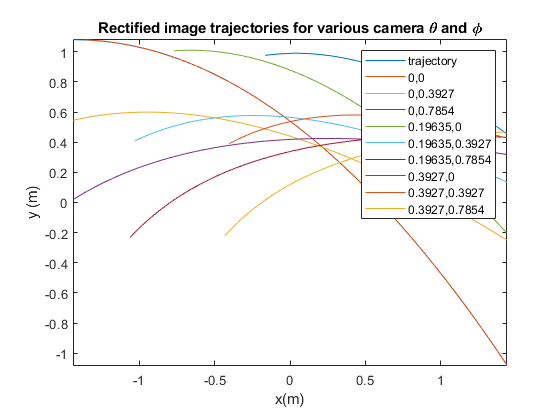

    plot(-M*xs(mask),-M*ys(mask),'-');
    legend('Trajectory',leg)% Add accumulated legend to plot
    end
end
hold off

## Simulation of iPhone images of a checkerboard

Let's create a planar checkerboard object, view it centered, and look how it appears when the camera points upwards. We will use a rotation around the 1-axis with angle $\chi$.

nrow=7;ncol=10;npix=5;% npix is the number of pixels per side of each square
zboard=12*.0254;% place 1 foot from camera
cbdimx = (9+1/16)*0.0254;% measured long side of checkerboard (m) when printed/pixel
ipoint=0;
M=zboard/fmag0;
nx=ncol*npix;ny=nrow*npix;
cbdim=(9+1/16)*0.0254/nx;
y=zeros(nx,ny);
ipoint=0;
for ix=1:nx
    for iy=1:ny
        if sin(ix*pi/npix)*sin(iy*pi/npix)>0
        ipoint=ipoint+1;
            xx(1,ipoint)=ix*cbdim;xx(2,ipoint)=iy*cbdim;
            xx(3,ipoint)=-zboard;
        end
    end
end

Center the checkerboard on the optical axis

xx(1,:)=xx(1,:)-cbdim*nx/2;xx(2,:)=xx(2,:)-cbdim*ny/2;

Plot checkerboard.

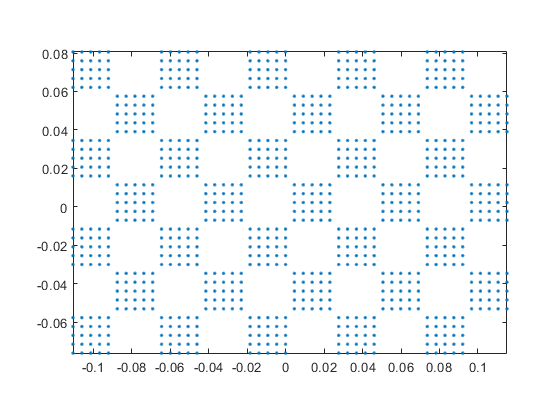

theta=0;phi=0;chi=0;
figure
plot(xx(1,:),xx(2,:),'.');axis image

figure
title('Checkerboard rectified images for various \chi')
M=zboard/fmag0;
leg=[];
x=xx;
for chi = [0:pi/8:+pi/4];
%    for chi = [0:0];
    leg=[leg,string(chi)];% build legend
    n1=[1;0;0];% initial sensor 1-direction (3x1)
    n2=[0;1;0];% initial sensor 2-direction
    n3=[0;0;1];% initial sensor 3-direction
    n=-n3; % initial direction of sensor towards pinhole
    Rtheta=[cos(theta),0,sin(theta);0,1,0;-sin(theta),0,cos(theta)];
    Rphi = [cos(phi),sin(phi),0;-sin(phi),cos(phi),0;0,0,1];
    Rchi = [1,0,0;0,cos(chi),sin(chi);0,-sin(chi),cos(chi)];
    R=Rchi*Rphi*Rtheta;% rotation matrix
    n=R*n;n1=R*n1;n2=R*n2;n3=R*n3;% rotated directions
    f=fmag0*n;% pinhole location also rotates with normal and camera
    lambda = -(n'*f)./(n'*(f-x));
    y=(1+lambda).*f -lambda.*x;% image points (3xN)
    plot(-M*n1'*y,-M*n2'*y,'.'); hold on;axis image
end

Add frame to the plot.

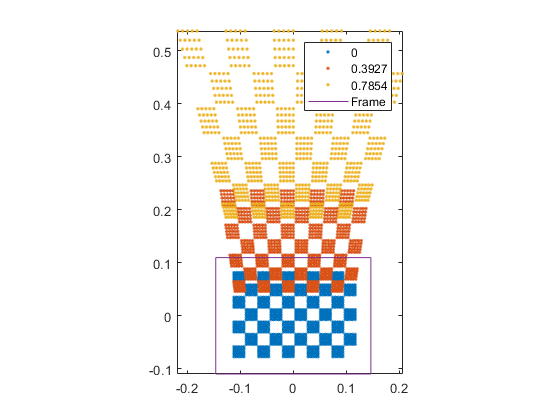

xm= pxmax*M; ym = pymax*M;
xframe=[xm,-xm,-xm,xm,xm];
yframe=[ym,ym,-ym,-ym,ym];
plot(xframe,yframe)
leg=[leg,string('Frame')];
legend(leg)% Add accumulated legend to plot
hold off

The end.